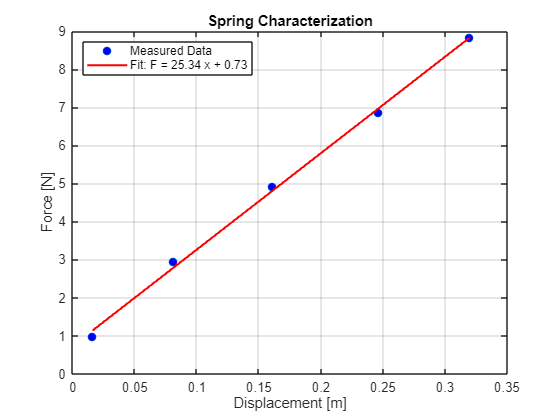

clear; 

%spring
l0 = 0.204; % natural length
lengths = [0.22, 0.285, 0.365, 0.45, 0.524]; % [m]
masses  = [0.1, 0.3, 0.5, 0.7, 0.9];         % [kg]

g = 9.81; 
forces = masses .* g; 

x = lengths - l0; % [m]

% F = k*x
p = polyfit(x, forces, 1);
k_single = p(1); % spring constant 
k_intercept = p(2);

k_eff = k_single / 2; % 2 identical springs in series

% force–displacement plot
figure;
plot(x, forces, 'o', 'MarkerFaceColor', 'b'); hold on;
plot(x, polyval(p, x), 'r-', 'LineWidth', 1.5);
xlabel('Displacement [m]');
ylabel('Force [N]');
title('Spring Characterization');
legend('Measured Data', sprintf('Fit: F = %.2f x + %.2f', k_single, k_intercept), 'Location', 'NorthWest');
grid on;

% acceleration

m = 0.720; 
data = readmatrix('Raw Data 3.csv');  

Error using readmatrix (line 171)
Unable to find or open 'Raw Data 3.csv'. Check the path and filename or file permissions.

t = data(:,1);
a_exp = data(:,2);
a_exp = smooth(a_exp, 10); %reduce noise

% damped harmonic model:
a_model = @(params, t) params(1) * exp(-params(2)*t) .* cos(params(3)*t + params(4));

% initial guesses
A0 = max(a_exp);
sigma0 = 0.2;
omega_d0 = 10; % [rad/s]
phi0 = 0;
params0 = [A0, sigma0, omega_d0, phi0];

% fit parameters 
opts = optimoptions('lsqcurvefit', 'Display', 'off');
params_fit = lsqcurvefit(a_model, params0, t, a_exp, [], [], opts);
A = params_fit(1);
sigma = params_fit(2);
omega_d = params_fit(3);
phi = params_fit(4);

a_fit = a_model(params_fit, t);

% Plot acceleration data
figure;
plot(t, a_exp, 'b', 'DisplayName', 'Experimental Accel'); hold on;
plot(t, a_fit, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Fitted Model');
xlabel('Time [s]');
ylabel('Acceleration [m/s^2]');
title('Acceleration Data and Fitted Model');
legend('Location', 'Best');
grid on;

% system parameters

omega_n_meas = sqrt(k_eff / m);

zeta = sigma / omega_n_meas;

omega_n_fit = sqrt(omega_d^2 + sigma^2);

c = 2 * m * sigma;

%% complex expo plot
lambda = [-sigma + 1i*omega_d, -sigma - 1i*omega_d];
figure;
plot(real(lambda), imag(lambda), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('Real part (-σ)');
ylabel('Imaginary part (±ω_d)');
title('Complex Exponential Coefficients');
grid on;
axis equal;

%results
fprintf('Mass (m):                %.4f kg\n', m);
fprintf('Single spring constant:  %.4f N/m\n', k_single);
fprintf('Effective spring const.: %.4f N/m\n', k_eff);
fprintf('Damping coefficient (c): %.4f N·s/m\n', c);
fprintf('Decay rate (σ):          %.4f 1/s\n', sigma);
fprintf('Damped frequency (ωd):   %.4f rad/s\n', omega_d);
fprintf('Natural freq (from m,k): %.4f rad/s\n', omega_n_meas);
fprintf('Natural freq (from data):%.4f rad/s\n', omega_n_fit);
fprintf('Damping ratio (ζ):       %.4f\n', zeta);
